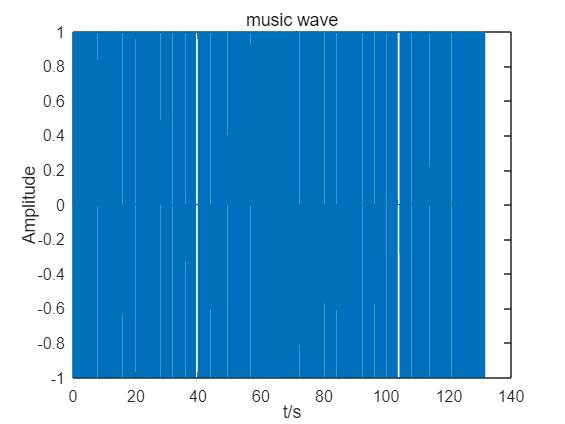

% 简谱生成音乐
tone = [6 7 1 7 1 3 7 3 3 6 5 6 1 5 0 3 3 4 3 4 1 3 0 1 1 1 7 4 4 7 7 0 6 7 1 7 1 3 7 0 3 3 6 5 6 1 5 0 3 4 1 7 7 1 2 2 3 1 0 1 7 6 6 7 5 6 0 1 2 3 2 3 5 2 0 5 5 1 7 1 3 3 0 0 6 7 1 7 2 2 1 5 5 0 4 3 2 1 3 3 0 3 6 5 5 3 2 1 0 1 2 1 2 2 5 3 0 3 6 5 3 2 1 0 1 2 1 2 2 7 6 0 6 7 1 7 1 3 7 3 3 6 5 6 1 5 0 3 3 4 3 4 1 3 0 1 1 1 7 4 4 7 7 0 6 7 1 7 1 3 7 0 3 3 6 5 6 1 5 0 3 4 1 7 7 1 2 2 3 1 0 1 7 6 6 7 5 6 0 1 2 3 2 3 5 2 0 5 5 1 7 1 3 3 0 0 6 7 1 7 2 2 1 5 5 0 4 3 2 1 3 3 0 3 6 5 5 3 2 1 0 1 2 1 2 2 5 3 0 3 6 5 3 2 1 0 1 2 1 2 2 7 6 0 6 7 6];
scale = 'D';
noctave = [0 0 1 0 1 1 0 0 0 0 0 0 1 0 0 0 0 0 0 0 1 0 0 1 1 1 0 0 0 0 0 0 0 0 1 0 1 1 0 0 0 0 0 0 0 1 0 0 0 0 1 0 0 1 1 1 1 1 0 1 0 0 0 0 0 0 0 1 1 1 1 1 1 1 0 0 0 1 0 1 1 1 0 0 0 0 1 0 1 1 1 0 0 0 1 1 1 1 1 1 0 1 1 1 1 1 1 1 0 1 1 1 1 1 1 1 0 1 1 1 1 1 1 0 1 1 1 1 1 0 0 0 0 0 1 0 1 1 0 0 0 0 0 0 1 0 0 0 0 0 0 0 1 0 0 1 1 1 0 0 0 0 0 0 0 0 1 0 1 1 0 0 0 0 0 0 0 1 0 0 0 0 1 0 0 1 1 1 1 1 0 1 0 0 0 0 0 0 0 1 1 1 1 1 1 1 0 0 0 1 0 1 1 1 0 0 0 0 1 0 1 1 1 0 0 0 1 1 1 1 1 1 0 1 1 1 1 1 1 1 0 1 1 1 1 1 1 1 0 1 1 1 1 1 1 0 1 1 1 1 1 0 0 0 0 0 0];
rising = [zeros(1,27), 1, 1, zeros(1,35), 1, zeros(1,69), zeros(1,25), 1, 1, zeros(1,35), 1, zeros(1,70)];
base_time = 0.5;
rhythm = base_time * [0.5 0.5 1.5 0.5 1 1 3 0.5 0.5 1.5 0.5 1 1 2 1 0.5 0.5 1.5 0.5 0.5 1.5 2 0.5 0.5 0.5 0.5 1.5 0.5 1 1 2 1 0.5 0.5 1.5 0.5 1 1 2 1 0.5 0.5 1.5 0.5 1 1 3 0.5 0.5 1 0.5 0.5 1 1 0.5 0.5 0.5 1 1 1 0.5 0.5 0.5 1 1 2 1 0.5 0.5 1.5 0.5 1 1 2 1 0.5 0.5 0.5 0.5 1 1 2 1 1 0.5 0.5 1 1 0.5 0.5 1.5 0.5 1 1 1 1 1 1 4 2 1 1 2 1 1 0.5 0.5 1 0.5 0.5 1 0.5 0.5 0.5 1 2 1 1 2 2 0.5 0.5 2 0.5 0.5 1 0.5 0.5 0.5 1 2 1 0.5 0.5 1.5 0.5 1 1 3 0.5 0.5 1.5 0.5 1 1 2 1 0.5 0.5 1.5 0.5 0.5 1.5 2 0.5 0.5 0.5 0.5 1.5 0.5 1 1 2 1 0.5 0.5 1.5 0.5 1 1 2 1 0.5 0.5 1.5 0.5 1 1 3 0.5 0.5 1 0.5 0.5 1 1 0.5 0.5 0.5 1 1 1 0.5 0.5 0.5 1 1 2 1 0.5 0.5 1.5 0.5 1 1 2 1 0.5 0.5 0.5 0.5 1 1 2 1 1 0.5 0.5 1 1 0.5 0.5 1.5 0.5 1 1 1 1 1 1 4 2 1 1 2 1 1 0.5 0.5 1 0.5 0.5 1 0.5 0.5 0.5 1 2 1 1 2 2 0.5 0.5 2 0.5 0.5 1 0.5 0.5 0.5 1 2 1 0.5 0.5 4];
fs=44100;
% t = linspace(0, sum(rhythm), fs*sum(rhythm));
% wave_segments = cell(1,267);
% for k=1:267
%     wave_segments{k} = gen_wave(tone(k),scale,noctave(k),rising(k),rhythm(k),fs);
% end
% wave_music = cell2mat(wave_segments);
% audiowrite('music.wav', wave_music, fs);
% player = audioplayer(wave_music, fs);
% play(player)
% plot(t,wave_music)
wave_music = gen_music(tone,scale,noctave,rising,rhythm,fs);

audiowrite('music.wav', wave_music, fs);
player = audioplayer(wave_music, fs);
%play(player)

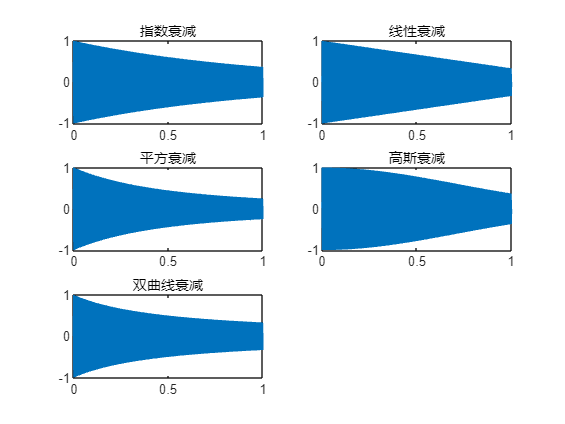

% 包络衰减
T=1;
wave = gen_wave(1,'A',0,0,T,fs);
t=linspace(0,T,T*fs);
wave1=wave.*exp(-t/T);
%sound(wave1,fs)

wave2=wave.*(1-t/(1.5*T));                                
%sound(wave2,fs)

wave3=wave./((1+t/T).^2);
%sound(wave3,fs)

wave4=wave.*exp(-(t/T).^2);
%sound(wave4,fs)

wave5=wave./(1+t/T*2);
%sound(wave5,fs)

figure
subplot(321)
plot(t,wave1)
title('指数衰减')
subplot(322)
plot(t,wave2)
title('线性衰减') 
subplot(323)
plot(t,wave3)
title('平方衰减')
subplot(324)
plot(t,wave4)
title('高斯衰减')
subplot(325)
plot(t,wave5)
title('双曲线衰减')

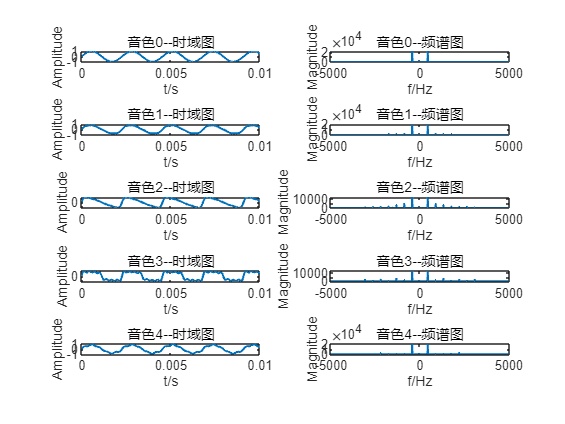

%音色调整
f= tone2freq(1,'A',0,0);
T = 1;
t=linspace(0,T,T*fs);
w = linspace(-fs/2,fs/2,length(t));

y0 = sin(2*pi*f*t);
y0_w = fftshift(fft(y0,length(y0)));

y1 = 0.8*sin(2*pi*f*t)+0.1*sin(2*pi*2*f*t)+0.05*sin(2*pi*3*f*t)+0.05*sin(2*pi*4*f*t); 
y1_w = fftshift(fft(y1,length(y1)));

y2 = 0.55*sin(2*pi*f*t)+0.2*sin(2*pi*2*f*t)+0.12*sin(2*pi*3*f*t)+0.06*sin(2*pi*4*f*t)+0.03*sin(2*pi*5*f*t)+0.025*sin(2*pi*6*f*t)+0.015*sin(2*pi*7*f*t);
y2_w = fftshift(fft(y2,length(y2)));

y3 = 0.55*sin(2*pi*f*t)+0.05*sin(2*pi*2*f*t)+0.15*sin(2*pi*3*f*t)+0.025*sin(2*pi*4*f*t)+0.1*sin(2*pi*5*f*t)+0.025*sin(2*pi*6*f*t)+0.1*sin(2*pi*7*f*t); 
y3_w = fftshift(fft(y3,length(y3)));

y4 = 0.8*sin(2*pi*f*t)+0.025*sin(2*pi*2*f*t)+0.025*sin(2*pi*3*f*t)+0.05*sin(2*pi*4*f*t)+0.1*sin(2*pi*5*f*t); 
y4_w = fftshift(fft(y4,length(y4)));

y = {y0 y1 y2 y3 y4};
y_w = {y0_w y1_w y2_w y3_w y4_w};
figure
for n=1:5
    subplot(5,2,2*n-1)
    plot(t,y{n},'LineWidth', 1.25);
    xlim([0,0.01])
    xlabel('t/s');
    ylabel('Amplitude')
    title("音色"+num2str(n-1)+"--时域图")
    subplot(5,2,2*n)
    plot(w,abs(y_w{n}),'LineWidth', 1.25)
    xlim([-5000,5000])
    xlabel('f/Hz');
    ylabel('Magnitude')
    title("音色"+num2str(n-1)+"--频谱图")
end

k0 = 1;
k1 = [0.8 0.1 0.05 0.05];%钢琴
k2 = [0.55 0.2 0.12 0.06 0.03 0.025 0.015];
k3 = [0.55 0.05 0.15 0.025 0.1 0.025 0.1];
k4 = [0.8 0.025 0.025 0.05 0.1];
p = [zeros(1,10), 1, zeros(1,41), 1, zeros(1,39), 1, zeros(1,6), 1, zeros(1,13), 1, zeros(1,14), 1, zeros(1,13), 1, zeros(1,41), 1, zeros(1,39), 1, zeros(1,6), 1, zeros(1,13), 1, zeros(1,14), 1, zeros(1,6)];


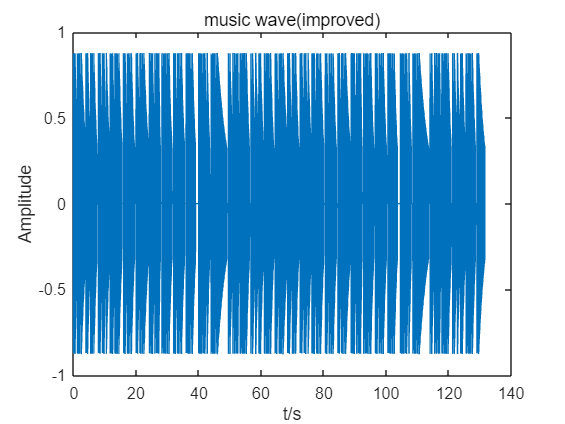

% wave_segments_new = cell(1,267);
% for k=1:267
%     wave_segments_new{k} = gen_wave2(tone(k),scale,noctave(k),rising(k),rhythm(k),fs,k2);
% end
% wave_music_new = cell2mat(wave_segments_new);
% audiowrite('music_new.wav', wave_music_new, fs);
% player = audioplayer(wave_music_new, fs);
% %play(player)
% figure
% plot(t,wave_music_new)
% xlabel('t/s');
% ylabel('Amplitude')
% title('整曲音乐波形图')
wave_music_new = gen_music2(tone,scale,noctave,rising,rhythm,fs,k4,p);

audiowrite('music_new.wav', wave_music_new, fs);
player_new = audioplayer(wave_music_new, fs);

%test1
f = tone2freq(3, 'C', 1, 0)

f = 658.9387

f = tone2freq(5, 'C', 0, -1)

f = 369.8168

f = tone2freq(7, 'A', -1, -1)

f = 391.9954

f = tone2freq(1, 'D', 0, 1)

f = 310.9524

f = tone2freq(2, 'E', 1, 1)

f = 783.6875

%test2
fs=8192;
wave = gen_wave(3,'C',0,-1,1,fs);

tone1 = [0 0 1 2 3 1 5 3 2 5 2 1 6 3 1 7 7 6 7 1 2 5 1 2 3 4 4 3 2 1 2 1 2 3 1 5 3 2 5 2 1 6 6 7 1 5 0 5 6 7 1 2 5 1 2 3 4 4 3 2 1 1 0 0 3 4 5 5 5 5 5 6 5 4 3 3 3 3 3 4 3 2 1 1 1 7 6 7 7 1 2 2 3 2 3 2 3 4 5 5 5 5 5 6 5 4 3 3 3 3 4 3 2 1 7 6 6 7 1 2 5 1 2 3 2 2 2 1 1 0 0 0 0 0 1 2 3 1 5 3 2 5 2 1 6 3 1 7 7 6 7 1 2 5 1 2 3 4 4 3 2 1 2 1 2 3 1 5 3 2 5 2 1 6 6 7 1 5 0 5 6 7 1 2 5 1 7 6 7 1 2 5 1 7 6 7 1 2 5 1 2 3 4 4 3 2 1 1 1 1 0 0 3 4 5 5 5 5 5 6 5 4 3 3 3 3 3 4 3 2 1 1 1 7 6 7 7 1 2 2 3 2 3 2 3 4 5 5 5 5 5 6 5 4 3 3 3 3 4 3 2 1 7 6 6 7 1 2 5 1 2 3 2 2 2 1 1 1 1 0 0 0];
tone2 = [0 0 0 5 1 7 5 6 6 7 1 7 5 7 3 4 4 3 2 2 5 0 5 1 7 5 6 6 3 3 4 3 2 3 1 1 2 3 0 0 0 1 1 1 2 1 7 6 6 6 1 5 5 3 6 6 6 3 4 4 6 5 6 5 6 5 0 1 1 1 2 1 7 6 6 6 1 5 5 3 1 1 4 3 3 2 5 5 3 0 0 0 0 0 0 5 1 7 5 6 6 7 1 7 5 7 3 4 4 3 0 2 2 5 0 5 1 7 5 6 6 3 3 4 3 2 3 1 1 1 4 3 5 4 4 3 5 2 2 5 5 5 0 0 0 1 1 1 2 1 7 6 6 6 1 5 5 3 6 6 6 3 4 4 6 5 6 5 6 5 0 1 1 1 2 1 7 6 6 6 1 5 5 3 4 4 4 3 3 2 5 5 3 3 3 5 1 3 5 1];
scale = 'F';
noctave1 = [zeros(1,12), -1, 0, 0, -1, -1, -1, -1, 0, 0, -1, zeros(1,19), -1, -1, -1, 0, -1, 0, -1, -1, -1, 0, 0, -1, zeros(1,32), -1, -1, -1, -1, zeros(1,25), -1, -1, -1, -1, 0, 0, -1, zeros(1,8), zeros(1,15), -1, 0, 0, -1, -1, -1, -1, 0, 0, -1, zeros(1,19), -1, -1, -1, 0, -1, 0, -1, -1, -1, 0, 0, -1, 0, -1, -1, -1, 0, 0, -1, 0, -1, -1, -1, 0, 0, -1, zeros(1,34), -1, -1, -1, -1, zeros(1,25), -1, -1, -1, -1, 0, 0, -1, zeros(1,13)];
noctave2 = [0, 0, 0, -1, 0, -1*ones(1,5), 0, -1*ones(1,10), 0, -1, 0, -1*ones(1,14), zeros(1,8), -1, -1, -1, -1, 0, -1*ones(1,15), zeros(1,6), -1, -1, -1, -1, 0, -1*ones(1,12), zeros(1,6), -1, 0, -1*ones(1,5), 0, -1*ones(1,7), 0, -1*ones(1,3), 0, -1, 0, -1*ones(1,25), zeros(1,8), -1*ones(1,4), 0, -1*ones(1,15), zeros(1,6), -1*ones(1,4), 0, -1*ones(1,15), zeros(1,4)];
rising1 = zeros(1,282);
rising2 = zeros(1,200);
base_time = 0.5;
rhythm1 = base_time .* [1 1 0.5 0.5 0.5 0.5 1.5 0.5 1 1 1 0.5 0.5 1.5 0.5 2 1 1 1 0.5 0.5 1 1 0.5 0.5 1 0.5 0.5 0.5 0.5 2 0.5 0.5 0.5 0.5 1.5 0.5 1 1 1 0.5 0.5 1 0.5 0.5 2 0.5 0.5 1 1 0.5 0.5 1 1 0.5 0.5 1 0.5 0.5 0.5 0.5 3 1 1 0.5 0.5 1 1 1 1 0.5 0.5 0.5 0.5 1 1 1 1 0.5 0.5 0.5 0.5 1 1 0.5 0.5 1 1 0.5 0.5 1 0.5 0.5 0.5 0.5 2 0.5 0.5 1 1 1 1 0.5 0.5 0.5 0.5 1 1 1 0.5 0.5 0.5 0.5 0.5 0.5 1 0.5 0.5 0.5 0.5 1 1 0.5 0.5 1.5 0.5 0.5 0.5 3 1 1 1 1 1 0.5 0.5 0.5 0.5 1.5 0.5 1 1 1 0.5 0.5 1.5 0.5 2 1 1 1 0.5 0.5 1 1 0.5 0.5 1 0.5 0.5 0.5 0.5 2 0.5 0.5 0.5 0.5 1.5 0.5 1 1 1 0.5 0.5 1 0.5 0.5 2 0.5 0.5 1 1 0.5 0.5 1 1.5 0.5 1 1 0.5 0.5 2 0.5 0.5 1 1 0.5 0.5 1 1 0.5 0.5 1 0.5 0.5 0.5 0.5 3 3 3 1 1 0.5 0.5 1 1 1 1 0.5 0.5 0.5 0.5 1 1 1 1 0.5 0.5 0.5 0.5 1 1 0.5 0.5 1 1 0.5 0.5 1 0.5 0.5 0.5 0.5 2 0.5 0.5 1 1 1 1 0.5 0.5 0.5 0.5 1 1 1 0.5 0.5 0.5 0.5 0.5 0.5 1 0.5 0.5 0.5 0.5 1 1 0.5 0.5 1.5 0.5 0.5 0.5 3 3 3 1 1 1];
rhythm2 = base_time .* [1 1 1 2 1 2 1 2 1 0.5 0.5 0.5 0.5 0.5 0.5 2 1 3 2 1 2 1 2 1 2 1 2 1 0.5 0.5 0.5 0.5 0.5 0.5 3 3 3 3 1 1 1 1 1 1 1.5 0.5 1 1 1 0.5 0.5 2 0.5 0.5 1 1 0.5 0.5 2 1 1 0.5 0.5 0.5 0.5 2 1 1 1 1 1.5 0.5 1 1 1 0.5 0.5 2 0.5 0.5 1 1 1 2 1 1.5 0.5 1 3 1 1 1 1 1 1 2 1 2 1 2 1 0.5 0.5 0.5 0.5 0.5 0.5 2 1 2 1 2 1 2 1 2 1 2 1 2 1 0.5 0.5 0.5 0.5 0.5 0.5 3 3 2 1 2 1 2 1 2 1 2 1 3 3 3 1 1 1 1 1 1 1.5 0.5 1 1 1 0.5 0.5 2 0.5 0.5 1 1 0.5 0.5 2 1 1 0.5 0.5 0.5 0.5 2 1 1 1 1 1.5 0.5 1 1 1 0.5 0.5 2 0.5 0.5 1 1 1 2 1 1.5 0.5 1 3 3 1 1 1 1 1 1];
fs=44100;
p1 = [zeros(1,208), 1, 1, zeros(1,67), 1, 1, 0, 0, 0];
p2 = [zeros(1,140), 1, 1, zeros(1,51), 1, zeros(1,6)];

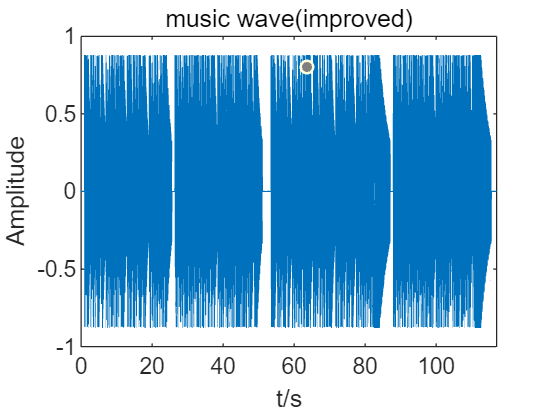

wave_music_part1 = gen_music2(tone1,scale,noctave1,rising1,rhythm1,fs,k4,p1);

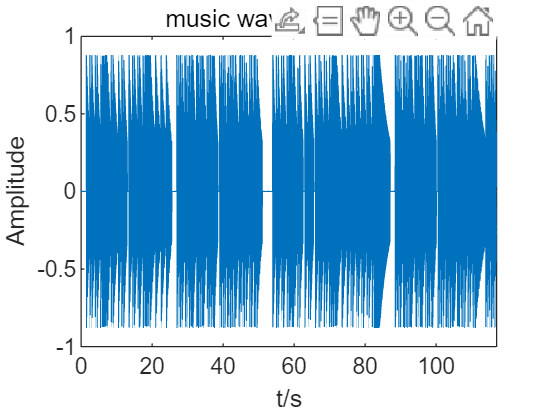

wave_music_part2 = gen_music2(tone2,scale,noctave2,rising2,rhythm2,fs,k4,p2);

wave_music_favor = [wave_music_part1.' , wave_music_part2.'];
audiowrite('music_favor.wav', wave_music_favor, fs);
player_favor = audioplayer(wave_music_favor, fs);
play(player_favor);